## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 09 - Four Point Rotational Springs**

**9.1 Potential of a four-point rotational springs**

Four-point rotational springs can be used to measure the bending stiffness and folding stiffness of plate like systems (see figure below). This is like a door hinge or other foldable structures we see in daily life. Here in this section, we will derive this rotational spring element in 3D space. What we will realize is that the derivation of four-point rotational spring is just like the three point rotational spring, except that the folding angle is calculated using four nodes rather than three. 

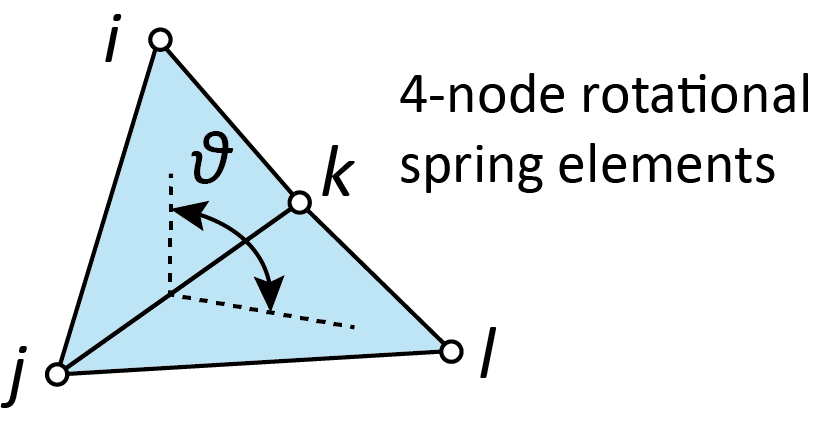

The way we can formulate a potential for this spring is to first find the angle $\theta \;\;$and then formulate potential of the spring from the angle. To find the $\theta$ angle, we can first find the normal vector for the two tiangles and then compute the angles between the two normals. This can be done using the following code: 

% Find the rotational spring angle from nodal coordinates
function theta = Find_Angle(xi,xj,xk,xl)
    % Find the normal for the first panel         
    vector1=xi-xj;
    vector2=xk-xj;
    % Normalize the length of vector
    vector1=vector1/norm(vector1);
    vector2=vector2/norm(vector2);
    normal1=cross(vector1,vector2);

    % Find the normal for the second panel
    vector1=xl-xj;
    vector2=xk-xj;
    % Normalize the length of vector
    vector1=vector1/norm(vector1);
    vector2=vector2/norm(vector2);
    normal2=cross(vector1,vector2);
    
    theta=acos(dot(normal1,normal2)/norm(normal1)/norm(normal2));
end

We can test out how this works:

% Define three nodes
xi=[1 0 0];
xj=[0 -1 0];
xk=[0 1 0];
xl=[0 0 1];
theta=Find_Angle(xi,xj,xk,xl);
theta

theta = 1.5708

Looking good! The angle is indeed 90 degree (1.57 rad). With this equation to calculate the rotational angle, we will be able to construct the potential based on the theta angle. For a linear elasti spring element, we can have:


$$U\left(\mathit{\mathbf{x}}\right)=\frac{1}{2}{K\left(\theta \;\left(\mathit{\mathbf{x}}\right)-\theta_0 \right)}^2$$


where the term $K$ is the stiffness of the rotational spring, and the term $\theta_0 \;$is the rest angle of the rotational spring. In addition, we also notice that the entire potential is a function of the nodal coordinates of the related nodes. The total potential can be formulated as:

% Find the rotational spring potential from nodal coordinates
function potential = Find_Potential(xi,xj,xk,xl,k,theta0)
    theta=Find_Angle(xi,xj,xk,xl);
    potential=1/2*((theta-theta0)^2)*k;
end

**9.2 Central Difference**

Now that we have the potential calculated and coded. We will follow the exact process in Section 02 and Section 06 to calculate the internal forces and the stiffness matrix. What we will realize is that the four node rotational spring is basically identical to the three-node rotational spring. Everything is the same except that we will now have a 12 by 1 force vector and a 12 by 12 stiffness matrix. 

Assuming that the four nodes are:


$${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} =\left\lbrack x_i ,y_i ,z_i \right\rbrack$$



$${\mathit{\mathbf{x}}}_j =\left\lbrack x_j ,y_j ,z_j \right\rbrack$$



$${\mathit{\mathbf{x}}}_k =\left\lbrack x_k ,y_k ,z_k \right\rbrack$$



$${\mathit{\mathbf{x}}}_l =\left\lbrack x_l ,y_l ,z_l \right\rbrack$$


The internal forces of the bar can be calculated as the Jacobian of the potential:


$${\mathit{\mathbf{F}}}_{\textrm{spr}} =\nabla_{\mathit{\mathbf{x}}} U_{\textrm{spr}}$$



$${\mathit{\mathbf{F}}}_{\mathbf{bar}} =\left\lbrack \begin{array}{c}
F_{x_{i\;} } \\
F_{y_{i\;} } \\
F_{z_{i\;} } \\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
F_{x_{l\;} } \\
F_{y_{l\;} } \\
F_{z_{l\;} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\partial U_{\mathrm{spr}} }{\partial x_i }\\
\frac{\partial U_{\mathrm{spr}} }{\partial y_i }\\
\frac{\partial U_{\mathrm{spr}} }{\partial z_i }\\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\frac{\partial U_{\mathrm{spr}} }{\partial x_l }\\
\frac{\partial U_{\mathrm{spr}} }{\partial y_l }\\
\frac{\partial U_{\mathrm{spr}} }{\partial z_l }
\end{array}\right\rbrack$$


Then, using the central difference method, we can calculate the values. We will only do the $x_{i\;}$and $y_i$ direction as an example:


$$\frac{\partial U_{\mathrm{spr}} }{\partial x_i }=\frac{U_{\mathrm{spr}\;} \left(x_i +\delta \;,y_{i\;} ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} ,x_l ,y_{l\;} ,z_{l\;} \right)-U_{\mathrm{spr}\;} \left(x_i -\delta \;,y_{i\;} ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} ,x_l ,y_{l\;} ,z_{l\;} \right)}{2\delta \;}\;$$



$$\frac{\partial U_{\mathrm{spr}} }{\partial y_i }=\frac{U_{\mathrm{spr}\;} \left(x_i \;,y_{i\;} +\delta ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} ,x_l ,y_{l\;} ,z_{l\;} \right)-U_{\mathrm{spr}\;} \left(x_i \;,y_{i\;} -\delta ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} ,x_l ,y_{l\;} ,z_{l\;} \right)}{2\delta \;}\;$$


We can repeat this for all 12 entries in the Jacobian vector and obtain the internal force vector. This calculation can be done using a for loop as the following:

function F=Local_Spr_Force(xi,xj,xk,xl,theta0,kspr,delta)
    F=zeros(12,1);
    % The local force vector is 12*1 vector
    for i=1:3
        x_forward=xi;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xi;
        x_backward(i)=x_backward(i)-delta;
        F(i)=(Find_Potential(x_forward,xj,xk,xl,kspr,theta0)-...
            Find_Potential(x_backward,xj,xk,xl,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % first node xi

        x_forward=xj;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xj;
        x_backward(i)=x_backward(i)-delta;
        F(3+i)=(Find_Potential(xi,x_forward,xk,xl,kspr,theta0)-...
            Find_Potential(xi,x_backward,xk,xl,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % second node xj

        x_forward=xk;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xk;
        x_backward(i)=x_backward(i)-delta;
        F(6+i)=(Find_Potential(xi,xj,x_forward,xl,kspr,theta0)-...
            Find_Potential(xi,xj,x_backward,xl,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % third node xk

        x_forward=xl;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xl;
        x_backward(i)=x_backward(i)-delta;
        F(9+i)=(Find_Potential(xi,xj,xk,x_forward,kspr,theta0)-...
            Find_Potential(xi,xj,xk,x_backward,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % third node xk
    end
end

**9.3 Internal Force Vector Example**

Let's visualize the above code to get a better understanding of the behavior of the rotational spring. When plotting the results, we will skip the y-direction because we assume that the rotational hinge lives in the x-z plane. However, we still calcualte the forces in 3D. 

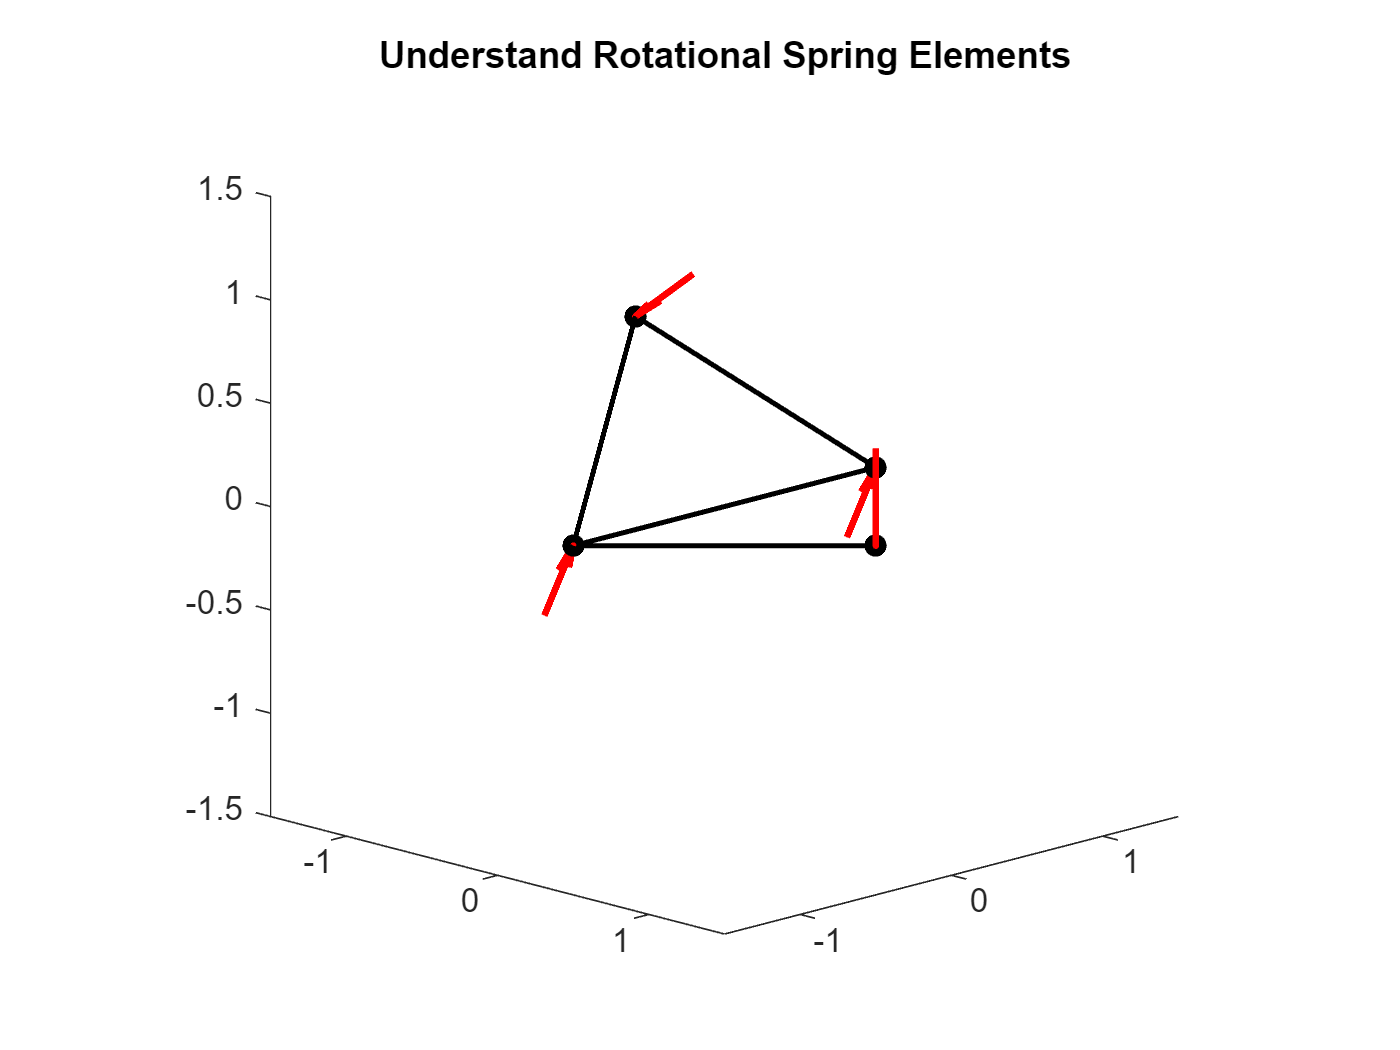

theta=0.7*pi; % The rotation angle
theta0=1*pi; % The stress free rotation angle

% The nodal coordinates of the rotational spring is 
% of the following values
xi=[1;0;0];
xj=[0;-1;0];
xk=[0;1;0];
xl=[cos(theta);0;sin(theta)];

kspr=1; % The rotational spring stiffness value
delta=10^-6; % Step length for the central difference method

% Solve for the forces of the rotational spring
% Here we can directly use the function we already created
sprForce=Local_Spr_Force(xi,xj,xk,xl,theta0,kspr,delta);

% Plot the figgure
figure
hold on
title('Understand Rotational Spring Elements')
set(gca,'DataAspectRatio',[1 1 1])
axis([-1.5,1.5,-1.5,1.5,-1.5,1.5])
view(45,15);
% This is the deformed bar location
plot3([xi(1),xj(1)],[xi(2),xj(2)],[xi(3),xj(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)
plot3([xj(1),xk(1)],[xj(2),xk(2)],[xj(3),xk(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)
plot3([xi(1),xk(1)],[xi(2),xk(2)],[xi(3),xk(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)
plot3([xj(1),xl(1)],[xj(2),xl(2)],[xj(3),xl(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)
plot3([xk(1),xl(1)],[xk(2),xl(2)],[xk(3),xl(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)

% Next we plot the forces acting on the spring
% We can use the Quiver function to do this
scaleFactor=-0.5;
% This is the force at the i-th node
quiver3(xi(1)-sprForce(1)*scaleFactor,...
    xi(2)-sprForce(2)*scaleFactor,...
    xi(3)-sprForce(3)*scaleFactor,...
    +sprForce(1)*scaleFactor,...
    +sprForce(2)*scaleFactor,...
    +sprForce(3)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)
% This is the force at the j-th node
quiver3(xj(1)-sprForce(4)*scaleFactor,...
    xj(2)-sprForce(5)*scaleFactor,...
    xj(3)-sprForce(6)*scaleFactor,...
    +sprForce(4)*scaleFactor,...
    +sprForce(5)*scaleFactor,...
    +sprForce(6)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)
% This is the force at the k-th node
quiver3(xk(1)-sprForce(7)*scaleFactor,...
    xk(2)-sprForce(8)*scaleFactor,...
    xk(3)-sprForce(9)*scaleFactor,...
    +sprForce(7)*scaleFactor,...
    +sprForce(8)*scaleFactor,...
    +sprForce(9)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)
% This is the force at the l-th node
quiver3(xl(1)-sprForce(10)*scaleFactor,...
    xl(2)-sprForce(11)*scaleFactor,...
    xl(3)-sprForce(12)*scaleFactor,...
    +sprForce(10)*scaleFactor,...
    +sprForce(11)*scaleFactor,...
    +sprForce(12)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)

Now, play with the stress free angle and the nodal coordinates, we can see that the forces do create a moment to close or open the three node hinge when the current rotational angle is not the same as the stress free angle. This behavior is just like what we expect to happen. 

**9.4 Hessian Matrix and Stiffness**

For this three-node rotational spring elements, the stiffness matrix can also be solved using the Hessian matrix of the potential of the system. Here, the matrix will be 12 by 12. Let's start to write this in block and start getting used to taking derivatives about vectors.


$${\mathit{\mathbf{K}}}_{\textrm{spr}} =\Delta_{\mathit{\mathbf{x}}} U_{\textrm{spr}} =\left\lbrack \begin{array}{ccc}
\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{i\;} \partial {\mathit{\mathbf{x}}}_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{i\;} \partial {\mathit{\mathbf{x}}}_{k\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{\mathit{\mathbf{j}}\;} \partial {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_j^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{j\;} \partial {\mathit{\mathbf{x}}}_{k\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{k\;} \partial {\mathit{\mathbf{x}}}_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{k\;} \partial {\mathit{\mathbf{x}}}_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_k^{2\;} }
\end{array}\right\rbrack$$


where each block is a 3 by 3 matrix. For example:


$$\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{i\;} \partial {\mathit{\mathbf{x}}}_{j\;} }=\left\lbrack \begin{array}{ccc}
\frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial x_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial y_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial z_{j\;} }
\end{array}\right\rbrack$$


Please note that bold represent vectors and each node is:

${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} =\left\lbrack x_{i\;} ,y_{i\;} ,z_{i\;} \right\rbrack$;

${\mathit{\mathbf{x}}}_j =\left\lbrack x_{j\;} ,y_{j\;} ,z_{j\;} \right\rbrack$;

${\mathit{\mathbf{x}}}_k =\left\lbrack x_k ,y_k ,z_{k\;} \right\rbrack$;

${\mathit{\mathbf{x}}}_l =\left\lbrack x_l ,y_l ,z_{l\;} \right\rbrack$;

Then, following the same mathematical trsanformation we did in Section 02, every column in the stiffness matrix can be writen as derivative of a force vector. For example, the first column of this stiffness matrix is:


$$\left\lbrack \begin{array}{c}
\frac{\partial^2 U_{\mathrm{spr}} }{\partial x_i^{2\;} }\\
\frac{\partial^2 U_{\mathrm{spr}} }{\partial y_{i\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\mathrm{spr}} }{\partial z_{i\;} \partial x_{i\;} }\\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\frac{\partial^2 U_{\mathrm{spr}} }{\partial x_{l\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\mathrm{spr}} }{\partial y_{l\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\mathrm{spr}} }{\partial z_{l\;} \partial x_{i\;} }
\end{array}\right\rbrack =\frac{\;\partial }{\;\partial \;x_{i\;} }\left\lbrack \begin{array}{c}
\frac{\partial U_{\mathrm{spr}} }{\partial x_i }\\
\frac{\partial U_{\mathrm{spr}} }{\partial y_i }\\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\frac{\partial U_{\mathrm{spr}} }{\partial y_l }\\
\frac{\partial U_{\mathrm{spr}} }{\partial z_l }
\end{array}\right\rbrack =\frac{\;\partial }{\;\partial \;x_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\mathrm{spr}} \right)$$


Basically, this is to apply central difference about the $x_{i\;}$direction again to the force vector we previously computed. This is the same derivation we did in the Section 06. Then, applying the above notation to the full matrix will give us:


$${\mathit{\mathbf{K}}}_{\mathrm{spr}} =\Delta_{\mathit{\mathbf{x}}} U_{\mathrm{spr}} =\left\lbrack \begin{array}{cccccc}
\frac{\;\partial }{\;\partial \;x_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\mathrm{spr}} \right) & \frac{\;\partial }{\;\partial \;y_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\mathrm{spr}} \right) & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \frac{\;\partial }{\;\partial \;y_l }\left(\nabla_{\mathit{\mathbf{x}}} U_{\mathrm{bar}} \right) & \frac{\;\partial }{\;\partial \;z_{l\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\mathrm{bar}} \right)
\end{array}\right\rbrack$$


This representation gives us a way to code this out easily! Basically, we are applying another central difference step to the internal force function we created previously for each column. This again is exactly what we did in section 06. This can be implemented with the following code:

function K=Local_Spr_Stiff(xi,xj,xk,xl,theta0,kspr,delta)
    K=zeros(12,12);
    % The local stiffness matrix is 12*12 matrix
    for i=1:3
        x_forward=xi;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xi;
        x_backward(i)=x_backward(i)-delta;
        K(i,:)=(Local_Spr_Force(x_forward,xj,xk,xl,theta0,kspr,delta)-...
            Local_Spr_Force(x_backward,xj,xk,xl,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % first node xi

        x_forward=xj;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xj;
        x_backward(i)=x_backward(i)-delta;
        K(3+i,:)=(Local_Spr_Force(xi,x_forward,xk,xl,theta0,kspr,delta)-...
            Local_Spr_Force(xi,x_backward,xk,xl,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % second node xj

        x_forward=xk;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xk;
        x_backward(i)=x_backward(i)-delta;
        K(6+i,:)=(Local_Spr_Force(xi,xj,x_forward,xl,theta0,kspr,delta)-...
            Local_Spr_Force(xi,xj,x_backward,xl,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % second node xk

        x_forward=xl;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xl;
        x_backward(i)=x_backward(i)-delta;
        K(9+i,:)=(Local_Spr_Force(xi,xj,xk,x_forward,theta0,kspr,delta)-...
            Local_Spr_Force(xi,xj,xk,x_backward,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % second node xl
    end
end

This code is almost identical to what we have in the force calculation. Again, this process is similar to Section 02 and Section 06. Now, let's compare the solution with the stock element in Sim-FAST:

**9.5 Compare with Stock Solution**

theta=0.8*pi; % The rotation angle
theta0=1*pi; % The stress free rotation angle
delta="10^-6";
kspr=1;

% The nodal coordinates of the rotational spring is 
% of the following values
xi=[1;0;0];
xj=[0;-1;0];
xk=[0;1;0];
xl=[cos(theta);0;sin(theta)];

% Group to a 4 by 3 matrix for stock element input
X=[xi,xj,xk,xl]';

spr=CD_Elements_RotSprings_4N();
spr.delta=delta;

force_stock=spr.Solve_Local_Force(X,theta0,kspr)

force_stock =          0
         0
    0.6283
   -0.1847
         0
   -0.5683
   -0.1847
         0
   -0.5683
    0.3693


force_this_code=Local_Spr_Force(xi,xj,xk,xl,theta0,kspr,delta)

force_this_code =          0
         0
    0.6283
   -0.1847
         0
   -0.5683
   -0.1847
         0
   -0.5683
    0.3693


stiff_stock=spr.Solve_Local_Stiff(X,theta0,kspr)

stiff_stock =          0         0   -0.6283         0         0    0.3140         0         0    0.3142         0         0         0
         0         0         0         0         0    0.3141         0         0   -0.3143         0         0         0
   -0.6283         0    1.0001    0.0202         0   -0.9044    0.0203         0   -0.9045    0.5878         0    0.8091
         0         0    0.0202    0.3104   -0.0923    0.1030    0.1609   -0.0923    0.2116   -0.4716    0.1847   -0.3349
         0         0         0   -0.0923         0   -0.2842    0.0924         0    0.2841         0         0         0
    0.3140    0.3141   -0.9044    0.1030   -0.2842    0.5942    0.2115   -0.2841    0.7435   -0.6288    0.2541   -0.4330
         0         0    0.0203    0.1609    0.0924    0.2115    0.3105    0.0923    0.1029   -0.4715   -0.1847   -0.3348
         0         0         0   -0.0923         0   -0.2841    0.0923         0    0.2841         0         0         0
    0.3142   -0.31

stiff_this_code=Local_Spr_Stiff(xi,xj,xk,xl,theta0,kspr,delta)

stiff_this_code =          0         0   -0.6284         0         0    0.3142         0         0    0.3142         0         0         0
         0         0         0         0         0    0.3142         0         0   -0.3142         0         0         0
   -0.6284         0    0.9999    0.0203    0.0001   -0.9047    0.0202         0   -0.9045    0.5877         0    0.8090
         0         0    0.0203    0.3105   -0.0923    0.1029    0.1610   -0.0923    0.2116   -0.4715    0.1847   -0.3349
         0         0    0.0001   -0.0923         0   -0.2841    0.0923         0    0.2841         0         0    0.0001
    0.3142    0.3142   -0.9047    0.1029   -0.2841    0.5941    0.2116   -0.2841    0.7434   -0.6286    0.2542   -0.4331
         0         0    0.0202    0.1610    0.0923    0.2116    0.3104    0.0923    0.1030   -0.4714   -0.1847   -0.3349
         0         0         0   -0.0923         0   -0.2841    0.0923         0    0.2841         0         0         0
    0.3142   -

The results are identical! Thus, we know that the dervied equations are correct!

In addition to play with the theta values, please also explore the different delta values for central difference step length. For the internal forces, the delta value does not change a lot of the results. However, the stiffness is sensitive to the selection of delta. Numerical error in the central difference can be a big problem that we need to consider when simulating for certain applications. 

This four-node rotational spring is quite important in the simulation of origami structures. Many recent simulation models (2015-2020) for active origami utilize this model. 